## Classification

% =========================================================================
% Standalone Classifier for Windowed EMG/Motion Features
% =========================================================================
% This script loads pre-extracted features and performs classification.
% It is divided into two main parts:
% PART I:  Classification using ALL features (EMG + Motion).
% PART II: Classification using ONLY EMG features.
% =========================================================================
clear;
clc;

## Step 1: Load Pre-Extracted Features

fprintf('=== Step 1: Loading Windowed Features ===\n');

=== Step 1: Loading Windowed Features ===



% Check if the feature file exists
if ~exist('./Features/WindowedFeatures.mat', 'file')
    error('Feature file not found. Please run the feature extraction script first.');
end

% Load the .mat file containing the features and metadata
load('./Features/WindowedFeatures.mat');

% Extract data from the loaded structure
X_orig = windowed_features.features;
y_orig = windowed_features.labels;
feature_names_orig = windowed_features.feature_names;
window_info = windowed_features.window_info;
class_names = windowed_features.class_names;

fprintf('✓ Loaded dataset from WindowedFeatures.mat\n');

✓ Loaded dataset from WindowedFeatures.mat


fprintf('Original dataset:\n');

Original dataset:


fprintf('  Total windows: %d\n', size(X_orig, 1));

  Total windows: 984


fprintf('  Features: %d\n', size(X_orig, 2));

  Features: 117



% Display class distribution from the loaded file
for i = 0:length(class_names)-1
    count = sum(y_orig == i);
    fprintf('  Class %d (%s): %d windows (%.1f%%)\n', i, class_names{i+1}, count, 100*count/length(y_orig));
end

  Class 0 (Chewing): 216 windows (22.0%)
  Class 1 (Swallowing): 539 windows (54.8%)
  Class 2 (Other): 229 windows (23.3%)


## PART I: CLASSIFICATION WITH ALL FEATURES (EMG + MOTION)

fprintf('  PART I: ANALYSIS WITH ALL FEATURES (EMG + MOTION)\n');

  PART I: ANALYSIS WITH ALL FEATURES (EMG + MOTION)


fprintf('========================================================================\n');

## PART I - Step 2: Data Cleaning & Selection (All Features)

fprintf('\n=== PART I - Step 2: Data Cleaning & Selection (All Features) ===\n');


=== PART I - Step 2: Data Cleaning & Selection (All Features) ===



X = X_orig;
y = y_orig;
feature_names = feature_names_orig;

% 1. Handle missing/infinite values
missing_count = sum(isnan(X(:)) | isinf(X(:)));
if missing_count > 0, fprintf('Replacing %d missing/infinite values with 0\n', missing_count); X(isnan(X) | isinf(X)) = 0; end

% 2. Remove constant features
feature_vars = var(X);
constant_features = feature_vars < 1e-10;
if any(constant_features), fprintf('Removing %d constant features\n', sum(constant_features)); X = X(:, ~constant_features); feature_names = feature_names(~constant_features); end

% 3. Feature scaling and selection
X_scaled = zscore(X);
scaled_vars = var(X_scaled);
low_var_threshold = 0.1;
good_features = scaled_vars > low_var_threshold;
X_selected = X_scaled(:, good_features);
selected_feature_names = feature_names(good_features);
fprintf('Selected %d features from %d after cleaning\n', size(X_selected, 2), size(X, 2));

Selected 117 features from 117 after cleaning


## PART I - Step 3: Cross-Validation (All Features)

fprintf('\n=== PART I - Step 3: Cross-Validation (All Features) ===\n');


=== PART I - Step 3: Cross-Validation (All Features) ===


k_folds = 5;
cv_indices = crossvalind('Kfold', y, k_folds);
rf_predictions = nan(size(y)); svm_predictions = nan(size(y)); xgb_predictions = nan(size(y));

for fold = 1:k_folds
    fprintf('Processing fold %d/%d...\n', fold, k_folds);
    test_mask = (cv_indices == fold); train_mask = ~test_mask;
    X_train = X_selected(train_mask, :); y_train = y(train_mask);
    X_test = X_selected(test_mask, :);
    train_classes = unique(y_train);
    if length(train_classes) < 2, fprintf('  Skipping fold - insufficient classes\n'); continue; end
    
    % --- Classifiers ---
    try rf_model = TreeBagger(50, X_train, y_train, 'Method', 'classification'); rf_predictions(test_mask) = str2double(predict(rf_model, X_test)); fprintf('  ✓ RF\n'); catch, fprintf('  ✗ RF failed\n'); end
    try svm_model = fitcecoc(X_train, y_train, 'Prior', 'uniform'); svm_predictions(test_mask) = predict(svm_model, X_test); fprintf('  ✓ SVM\n'); catch, fprintf('  ✗ SVM failed\n'); end
    try t = templateTree('MaxNumSplits', 5); rus_model = fitcensemble(X_train, y_train, 'Method', 'RUSBoost', 'Learners', t); xgb_predictions(test_mask) = predict(rus_model, X_test); fprintf('  ✓ RUSBoost\n'); catch, fprintf('  ✗ RUSBoost failed\n'); end
end

Processing fold 1/5...


  ✓ RF


  ✓ SVM


  ✓ RUSBoost


Processing fold 2/5...


  ✓ RF


  ✓ SVM


  ✓ RUSBoost


Processing fold 3/5...


  ✓ RF


  ✓ SVM


  ✓ RUSBoost


Processing fold 4/5...


  ✓ RF


  ✓ SVM


  ✓ RUSBoost


Processing fold 5/5...


  ✓ RF


  ✓ SVM


  ✓ RUSBoost


## PART I - Step 4: Evaluation & Feature Importance (All Features)

fprintf('\n=== PART I - Step 4: Evaluation & Importance (All Features) ===\n');


=== PART I - Step 4: Evaluation & Importance (All Features) ===


% --- Evaluation ---
if ~all(isnan(rf_predictions)), rf_acc_full = sum(y == rf_predictions, 'omitnan') / sum(~isnan(rf_predictions)); fprintf('Random Forest Accuracy: %.1f%%\n', rf_acc_full*100); end

Random Forest Accuracy: 99.5%


if ~all(isnan(svm_predictions)), svm_acc_full = sum(y == svm_predictions, 'omitnan') / sum(~isnan(svm_predictions)); fprintf('SVM Accuracy: %.1f%%\n', svm_acc_full*100); end

SVM Accuracy: 99.5%


if ~all(isnan(xgb_predictions)), xgb_acc_full = sum(y == xgb_predictions, 'omitnan') / sum(~isnan(xgb_predictions)); fprintf('RUSBoost (XGB) Accuracy: %.1f%%\n', xgb_acc_full*100); end

RUSBoost (XGB) Accuracy: 90.7%


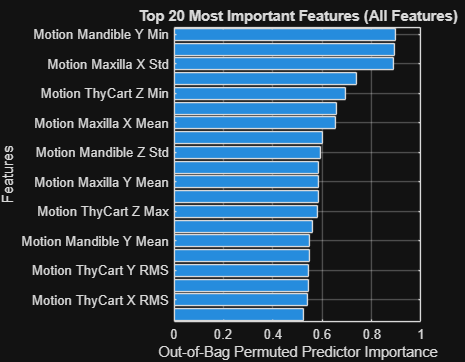

✓ Feature importance plot for ALL features created.



% --- Feature Importance ---
try
    final_rf_full = TreeBagger(50, X_selected, y, 'Method', 'classification', 'OOBPredictorImportance', 'on');
    importance_full = final_rf_full.OOBPermutedPredictorDeltaError;
    [sorted_importance_full, sort_idx_full] = sort(importance_full, 'descend');
    
    % --- Visualization ---
    num_features_to_plot = 20;
    top_n = min(num_features_to_plot, length(sorted_importance_full));
    plot_importance = sorted_importance_full(1:top_n);
    plot_names = selected_feature_names(sort_idx_full(1:top_n));
    
    % FIX: Replace underscores for clean plotting
    plot_names_clean = replace(plot_names, '_', ' ');
    
    figure('Name', 'Feature Importance (All Features)', 'Position', [100, 100, 900, 700]);
    barh(flip(plot_importance));
    yticklabels(flip(plot_names_clean));
    xlabel('Out-of-Bag Permuted Predictor Importance');
    ylabel('Features');
    title(sprintf('Top %d Most Important Features (All Features)', top_n));
    grid on; ylim([0.5, top_n + 0.5]);
    fprintf('✓ Feature importance plot for ALL features created.\n');
catch ME
    fprintf('Full feature importance analysis failed: %s\n', ME.message);
end

## PART II: CLASSIFICATION WITH EMG FEATURES ONLY

fprintf('\n\n========================================================================\n');

fprintf('  PART II: ANALYSIS WITH EMG FEATURES ONLY\n');

  PART II: ANALYSIS WITH EMG FEATURES ONLY


fprintf('========================================================================\n');

## PART II - Step 1: Select EMG Data

fprintf('\n=== PART II - Step 1: Selecting EMG Features ===\n');


=== PART II - Step 1: Selecting EMG Features ===


emg_feature_mask = startsWith(feature_names_orig, 'EMG_');
X_emg_orig = X_orig(:, emg_feature_mask);
feature_names_emg_orig = feature_names_orig(emg_feature_mask);
fprintf('Selected %d EMG features out of %d total original features.\n', size(X_emg_orig, 2), size(X_orig, 2));

Selected 27 EMG features out of 117 total original features.


## PART II - Step 2: Data Cleaning & Selection (EMG Only)

fprintf('\n=== PART II - Step 2: Data Cleaning & Selection (EMG Only) ===\n');


=== PART II - Step 2: Data Cleaning & Selection (EMG Only) ===


X_emg = X_emg_orig;
y_emg = y_orig; % Labels are the same
feature_names_emg = feature_names_emg_orig;

% 1. Handle missing/infinite values
missing_count_emg = sum(isnan(X_emg(:)) | isinf(X_emg(:)));
if missing_count_emg > 0, fprintf('Replacing %d missing/infinite values with 0\n', missing_count_emg); X_emg(isnan(X_emg) | isinf(X_emg)) = 0; end

% 2. Remove constant features
feature_vars_emg = var(X_emg);
constant_features_emg = feature_vars_emg < 1e-10;
if any(constant_features_emg), fprintf('Removing %d constant EMG features\n', sum(constant_features_emg)); X_emg = X_emg(:, ~constant_features_emg); feature_names_emg = feature_names_emg(~constant_features_emg); end

% 3. Feature scaling and selection
X_emg_scaled = zscore(X_emg);
scaled_vars_emg = var(X_emg_scaled);
good_features_emg = scaled_vars_emg > low_var_threshold; % Use same threshold
X_emg_selected = X_emg_scaled(:, good_features_emg);
selected_feature_names_emg = feature_names_emg(good_features_emg);
fprintf('Selected %d EMG features from %d after cleaning\n', size(X_emg_selected, 2), size(X_emg, 2));

Selected 27 EMG features from 27 after cleaning


## PART II - Step 3: Cross-Validation (EMG Only)

fprintf('\n=== PART II - Step 3: Cross-Validation (EMG Only) ===\n');


=== PART II - Step 3: Cross-Validation (EMG Only) ===


rf_emg_predictions = nan(size(y)); svm_emg_predictions = nan(size(y)); xgb_emg_predictions = nan(size(y));

for fold = 1:k_folds
    fprintf('Processing fold %d/%d...\n', fold, k_folds);
    test_mask = (cv_indices == fold); train_mask = ~test_mask;
    X_train = X_emg_selected(train_mask, :); y_train = y_emg(train_mask);
    X_test = X_emg_selected(test_mask, :);
    train_classes = unique(y_train);
    if length(train_classes) < 2, fprintf('  Skipping fold - insufficient classes\n'); continue; end

    % --- Classifiers ---
    try rf_model = TreeBagger(50, X_train, y_train, 'Method', 'classification'); rf_emg_predictions(test_mask) = str2double(predict(rf_model, X_test)); fprintf('  ✓ RF\n'); catch, fprintf('  ✗ RF failed\n'); end
    try svm_model = fitcecoc(X_train, y_train, 'Prior', 'uniform'); svm_emg_predictions(test_mask) = predict(svm_model, X_test); fprintf('  ✓ SVM\n'); catch, fprintf('  ✗ SVM failed\n'); end
    try t = templateTree('MaxNumSplits', 5); rus_model = fitcensemble(X_train, y_train, 'Method', 'RUSBoost', 'Learners', t); xgb_emg_predictions(test_mask) = predict(rus_model, X_test); fprintf('  ✓ RUSBoost\n'); catch, fprintf('  ✗ RUSBoost failed\n'); end
end

Processing fold 1/5...


  ✓ RF


  ✓ SVM


  ✓ RUSBoost


Processing fold 2/5...


  ✓ RF


  ✓ SVM


  ✓ RUSBoost


Processing fold 3/5...


  ✓ RF


  ✓ SVM


  ✓ RUSBoost


Processing fold 4/5...


  ✓ RF


  ✓ SVM


  ✓ RUSBoost


Processing fold 5/5...


  ✓ RF


  ✓ SVM


  ✓ RUSBoost


## PART II - Step 4: Evaluation & Feature Importance (EMG Only)

fprintf('\n=== PART II - Step 4: Evaluation & Importance (EMG Only) ===\n');


=== PART II - Step 4: Evaluation & Importance (EMG Only) ===


% --- Evaluation ---
if ~all(isnan(rf_emg_predictions)), rf_acc_emg = sum(y_emg == rf_emg_predictions, 'omitnan') / sum(~isnan(rf_emg_predictions)); fprintf('Random Forest Accuracy (EMG Only): %.1f%%\n', rf_acc_emg*100); end

Random Forest Accuracy (EMG Only): 86.9%


if ~all(isnan(svm_emg_predictions)), svm_acc_emg = sum(y_emg == svm_emg_predictions, 'omitnan') / sum(~isnan(svm_emg_predictions)); fprintf('SVM Accuracy (EMG Only): %.1f%%\n', svm_acc_emg*100); end

SVM Accuracy (EMG Only): 81.3%


if ~all(isnan(xgb_emg_predictions)), xgb_acc_emg = sum(y_emg == xgb_emg_predictions, 'omitnan') / sum(~isnan(xgb_emg_predictions)); fprintf('RUSBoost (XGB) Accuracy (EMG Only): %.1f%%\n', xgb_acc_emg*100); end

RUSBoost (XGB) Accuracy (EMG Only): 66.7%


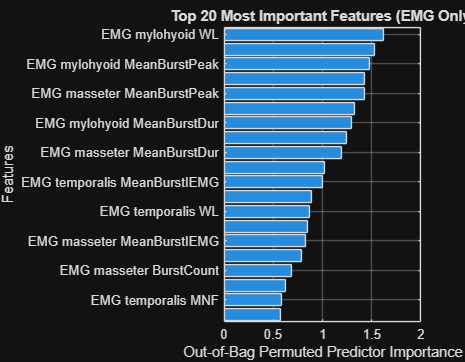

✓ Feature importance plot for EMG features created.



% --- Feature Importance ---
try
    final_rf_emg = TreeBagger(50, X_emg_selected, y_emg, 'Method', 'classification', 'OOBPredictorImportance', 'on');
    importance_emg = final_rf_emg.OOBPermutedPredictorDeltaError;
    [sorted_importance_emg, sort_idx_emg] = sort(importance_emg, 'descend');
    
    % --- Visualization ---
    num_features_to_plot = 20;
    top_n = min(num_features_to_plot, length(sorted_importance_emg));
    plot_importance = sorted_importance_emg(1:top_n);
    plot_names = selected_feature_names_emg(sort_idx_emg(1:top_n));
    
    % FIX: Replace underscores for clean plotting
    plot_names_clean = replace(plot_names, '_', ' ');
    
    figure('Name', 'Feature Importance (EMG Only)', 'Position', [100, 100, 900, 700]);
    barh(flip(plot_importance));
    yticklabels(flip(plot_names_clean));
    xlabel('Out-of-Bag Permuted Predictor Importance');
    ylabel('Features');
    title(sprintf('Top %d Most Important Features (EMG Only)', top_n));
    grid on; ylim([0.5, top_n + 0.5]);
    fprintf('✓ Feature importance plot for EMG features created.\n');
catch ME
    fprintf('EMG-only feature importance analysis failed: %s\n', ME.message);
end

## Final Step: Save All Results

fprintf('\n=== Final Step: Saving All Results ===\n');


=== Final Step: Saving All Results ===


results = struct();
results.all_features.rf_predictions = rf_predictions;
results.all_features.svm_predictions = svm_predictions;
results.all_features.xgb_predictions = xgb_predictions;
if exist('rf_acc_full','var'), results.all_features.rf_accuracy = rf_acc_full; end
if exist('svm_acc_full','var'), results.all_features.svm_accuracy = svm_acc_full; end
if exist('xgb_acc_full','var'), results.all_features.xgb_accuracy = xgb_acc_full; end

results.emg_only.rf_predictions = rf_emg_predictions;
results.emg_only.svm_predictions = svm_emg_predictions;
results.emg_only.xgb_predictions = xgb_emg_predictions;
if exist('rf_acc_emg','var'), results.emg_only.rf_accuracy = rf_acc_emg; end
if exist('svm_acc_emg','var'), results.emg_only.svm_accuracy = svm_acc_emg; end
if exist('xgb_acc_emg','var'), results.emg_only.xgb_accuracy = xgb_acc_emg; end

results.true_labels = y_orig;
results.class_names = class_names;
results.window_info = window_info;

save('./ClassificationResult/ClassifierResults_Comparison.mat', 'results');
fprintf('✓ All comparison results saved to ClassifierResults_Comparison.mat\n');

✓ All comparison results saved to ClassifierResults_Comparison.mat
